# Лабораторная работа №7

Решение АПСЗ LR методом.

n = 10;
eps = 1e-12;
disp('Собственные числа:')

Собственные числа:


d = randi(100, n, 1)

d =     82
    91
    13
    92
    64
    10
    28
    55
    96
    97


A = gen_matr2(d);
VX = [];
[L, U] = LUfanc(A);
[A0, iter] = (LR(n, eps, A, L, U));
for index = 1:n
    [X, d] = get_eigvalues(A0', index, n, A);
    VX = [VX X];
end

disp('Количество итераций:');

Количество итераций:


iter

iter = 2125

disp('Столбец собственных чисел (числа с диагонали):');

Столбец собственных чисел (числа с диагонали):


d

d =    97.0000
   96.0000
   91.0001
   91.9999
   82.0000
   64.0000
   55.0000
   28.0000
   13.0000
   10.0000


disp('Матрица из собственных векторов:');

Матрица из собственных векторов:


VX

VX =     0.1726    0.0672   -0.2933    0.1070   -0.7169    0.3019    0.3708   -0.2244   -0.0538   -0.0870
    0.2613   -0.0182    0.6640    0.5689    0.3060    0.3542    0.4051   -0.2545   -0.0552   -0.0952
    0.0195    0.0205   -0.0521    0.0072    0.0475    0.0680    0.0600    0.0095    0.9932    0.0376
   -0.0658   -0.3646    0.2798    0.8146   -0.2547   -0.2996   -0.3119    0.1875    0.0357    0.0974
   -0.1156   -0.1944    0.3542   -0.0210   -0.3227    0.6242   -0.3203    0.2408    0.0453    0.1188
   -0.0273   -0.0568    0.1032   -0.0061   -0.0940   -0.1094   -0.1287    0.1005    0.0132   -0.9661
    0.0953    0.1126   -0.2427    0.0144    0.2211    0.2571    0.2508    0.8258   -0.0310   -0.0758
    0.1339    0.1604   -0.3655    0.0216    0.3329    0.3872   -0.5759   -0.2597   -0.0467   -0.1142
    0.1700   -0.8793   -0.1522    0.0090    0.1387    0.1613    0.1748   -0.1082   -0.0195   -0.0476
    0.9095   -0.0966    0.2010   -0.0119   -0.1831   -0.2129   -0.2307    0.1428    0.

disp('Решение с помощью встроенных функций MATLAB:');

Решение с помощью встроенных функций MATLAB:


[V D] = eig(A);
V

V =     0.0870    0.0538   -0.2244   -0.3708   -0.3019   -0.7169    0.2934   -0.1070    0.1726   -0.0672
    0.0952    0.0552   -0.2545   -0.4051   -0.3542    0.3060   -0.6639   -0.5688    0.2613    0.0182
   -0.0376   -0.9932    0.0095   -0.0600   -0.0680    0.0475    0.0521   -0.0072    0.0195   -0.0205
   -0.0974   -0.0357    0.1875    0.3119    0.2996   -0.2547   -0.2796   -0.8146   -0.0658    0.3646
   -0.1188   -0.0453    0.2408    0.3203   -0.6242   -0.3227   -0.3543    0.0210   -0.1156    0.1944
    0.9661   -0.0132    0.1005    0.1287    0.1094   -0.0940   -0.1032    0.0061   -0.0273    0.0568
    0.0758    0.0310    0.8258   -0.2508   -0.2571    0.2211    0.2427   -0.0144    0.0953   -0.1126
    0.1142    0.0467   -0.2597    0.5759   -0.3872    0.3329    0.3655   -0.0216    0.1339   -0.1604
    0.0476    0.0195   -0.1082   -0.1748   -0.1613    0.1387    0.1523   -0.0090    0.1700    0.8793
   -0.0628   -0.0257    0.1428    0.2307    0.2129   -0.1831   -0.2010    0.0119    0.9

diag(D)

ans =    10.0000
   13.0000
   28.0000
   55.0000
   64.0000
   82.0000
   91.0000
   92.0000
   97.0000
   96.0000


norm(sort(abs(VX), 2) - sort(abs(V), 2))

ans = 1.9382e-04

[N, XX, LL, AL, E] = get_ne(-1, -16, 40, 1);

CЧ


d =     42
    85
    84
    26
    62
    59
    55
    87
    27
    32


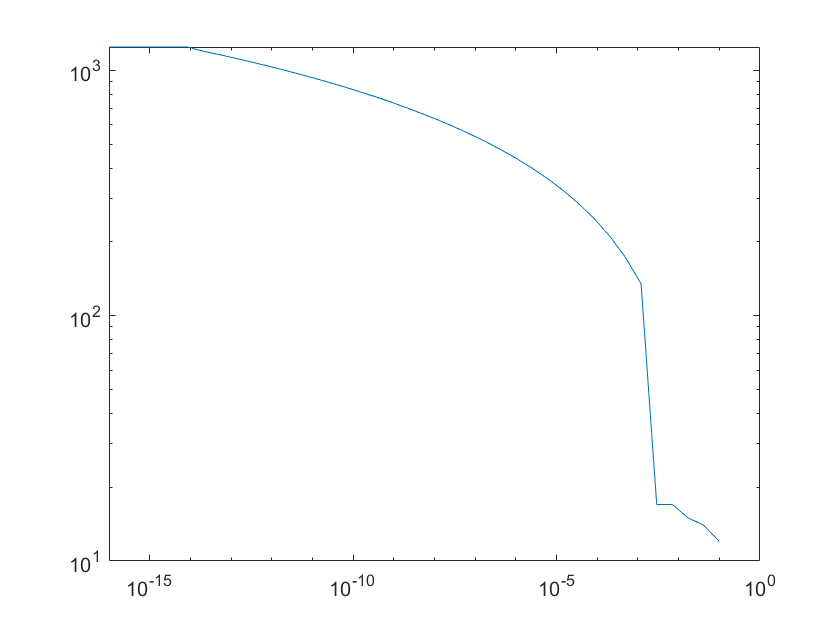

loglog(E, N);

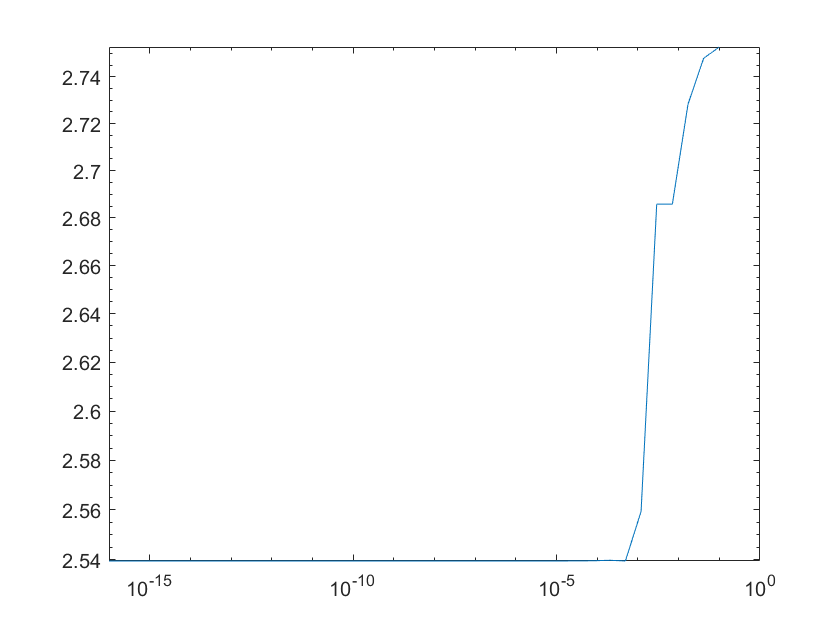

loglog(E, XX);

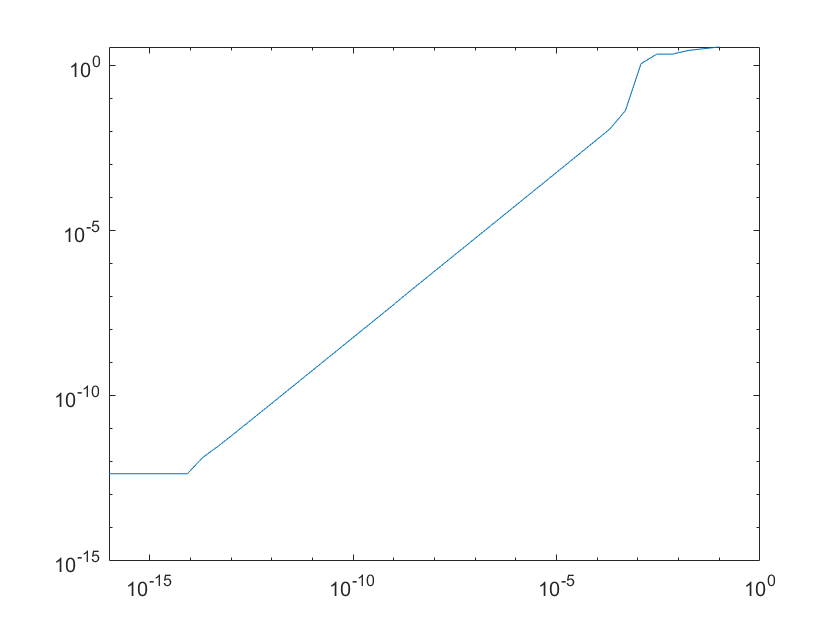

loglog(E, LL);

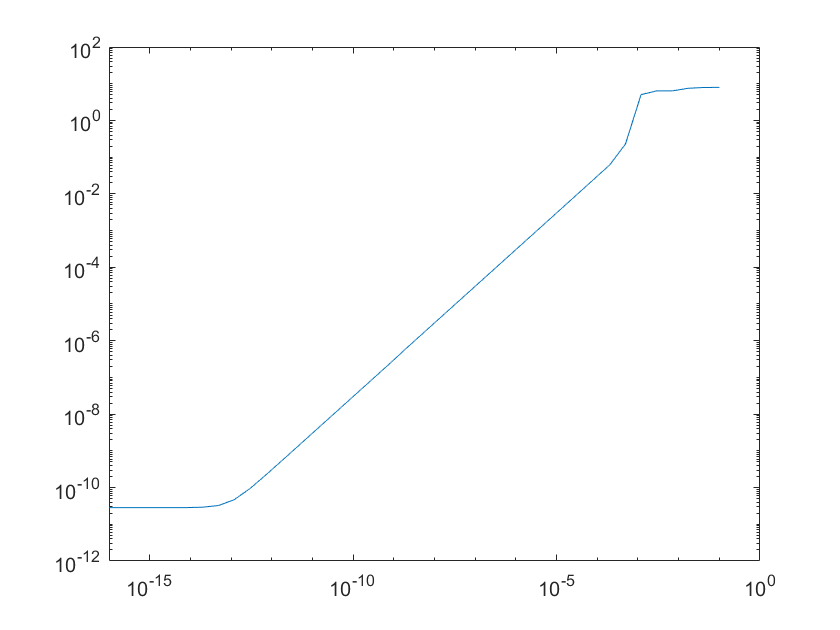

loglog(E, AL);

Для матрицы со сдвигом:

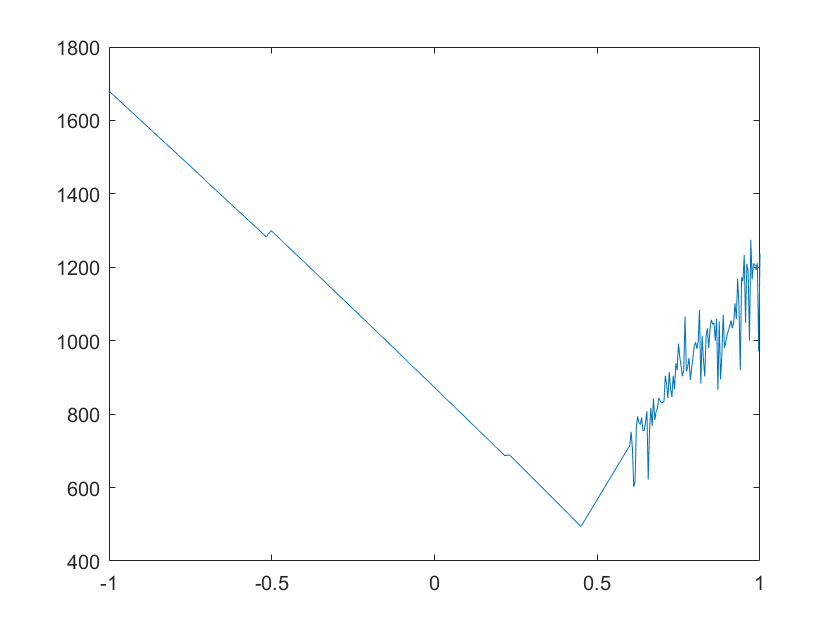

d = randi(100, n, 1);
A = gen_matr2(d);
[N, X] = calc_sdv(A, -1, 1, 100);
plot(X, N)

function A = gen_matr2(d)
    n = max(size(d));
    for i = 1:n
        for j = i+1:n
            A(i, j) = rand;
        end
        A(i, i) = d(i);
    end
    w = sin([1:1:n])';
    P = eye(n) - (2 * w * w')/(w' * w); 
    A = P*A*P'; 
end 

function [N, XX, LL, AL, eps_v] = get_ne(emin, emax, step, flag)
    eps_v = logspace(emin, emax, step);
    N = zeros(1, max(size(eps_v)));
    XX = zeros(1, max(size(eps_v)));
    LL = zeros(1, max(size(eps_v)));
    AL = zeros(1, max(size(eps_v)));
    if flag
        disp('CЧ')
        d = randi(100, 10, 1)
    else
        disp('CЧ')
        d = 10.*ones(10, 1) + rand(10, 1)./10
    end
    A = gen_matr2(d);
    n = max(size(A));
    [L, U] = LUfanc(A);
    [A0, iter] = (LR(n, eps, A, L, U));
    [V, D] = eig(A0');
    D = diag(D);
    
    nij = max(size(eps_v));
    for i = 1:nij
        [d, VX, iter] = calc_sv(A, n, eps_v(i));
        N(i) = iter;
        XX(i) = norm(sort(abs(VX), 2) - sort(abs(V), 2));
        LL(i) = norm(sort(D) - sort(d));
        AL(i) = norm(A*VX - VX*diag(d));
    end
end

function [d, VX, iter] = calc_sv(A, n, eps)
    VX = [];
    [L, U] = LUfanc(A);
    [A0, iter] = (LR(n, eps, A, L, U));
    for index = 1:n
        [X, d] = get_eigvalues(A0', index, n, A);
        VX = [VX X];
    end
end

function [N, X] = calc_sdv(A, min, maxx, step)
    lm = max(eig(A));
    X = linspace(min, 0.45, step);
    X = [X linspace(0.6, maxx, step)];
    N = [];
    n = size(A);
    for i = 1:max(size(X))
        As = A - lm*X(i)*eye(n);
        [L, U] = LUfanc(As);
        [A0, iter] = (LR(n, eps, As, L, U));
        N(i) = iter;
    end
end